# **Task 2: Compress an AI Model for Deployment **

In Task 1, you trained a deep neural network for bearing fault diagnosis. To deploy this model on a resource‑constrained embedded system for use in a *smart* appliance, the model must be optimized for memory usage and inference latency.

In this task, you will apply **three model compression techniques** to reduce the size and computational cost of the trained network while preserving diagnostic accuracy. These techniques include two **structural compression methods** and one **data type conversion** method, which together target reductions in flash memory, RAM usage, and execution time.

First, you will apply **Taylor Pruning**, a structural compression method that analyzes the sensitivity of the loss function to individual channels and removes those with the least contribution. This step reduces the number of parameters and operations in the CNN. Next, you will use **Projection**, a structural compression technique based on **principal component analysis (PCA)**, to further reduce model size by projecting learned features onto a lower‑dimensional subspace. Finally, once the structurally compressed model meets performance requirements, you will apply **quantization** to convert the model from single‑precision (32‑bit) floating point to 8‑bit integer data types, enabling efficient deployment on embedded hardware.

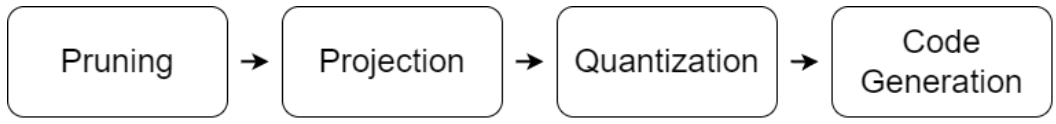

To learn more about [Reduce Memory Footprint of Deep Neural Networks](https://www.mathworks.com/help/deeplearning/ug/reduce-memory-footprint-of-deep-neural-networks.html)

## 1. Analyze Network for Compression

Load and preprocess the data the same way as task 1. You will need (at least part of) the training and validation data for model fine-tuning to perform model compression.

load("valTable.mat")
load("trainTable.mat")
load("testTable.mat")
% Prepare Data
allTrainData = cell2mat(trainTable{:,4});
muTrain = table2array(mean(allTrainData));
sigmaTrain = table2array(std(allTrainData));
% Get Training Data and Normalize
XTrain = cell2mat(cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(trainTable(:,4)),'UniformOutput',false)');
XTest = cell2mat(cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(testTable(:,4)),'UniformOutput',false)');
XVal = cell2mat(cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(valTable(:,4)),'UniformOutput',false)');
YTrain = categorical(string(trainTable.label));
YTest = categorical(string(testTable.label));
YVal = categorical(string(valTable.label));
% Reshape the data to align with any hardware parsing requirement
XTrain = reshape(XTrain,[size(XTrain,1),1,size(XTrain,2)]);
XTest = reshape(XTest,[size(XTest,1),1,size(XTest,2)]);
XVal = reshape(XVal,[size(XVal,1),1,size(XVal,2)]);

Load the original network trained from task 1

load("original_net.mat")
accuracyNetOriginal = testnet(net,XTest,YTest,"accuracy")

accuracyNetOriginal = 100

Execute the command below to open Deep Network Designer with the dlnetwork object from Deep Learning Toolbox™. To assess how much compression can be achieved, click the Analyze for Compression button in the toolstrip. The analysis report will indicate that the network can be compressed using pruning, projection, or quantization, either individually or in combination.

>> deepNetworkDesigner(net)

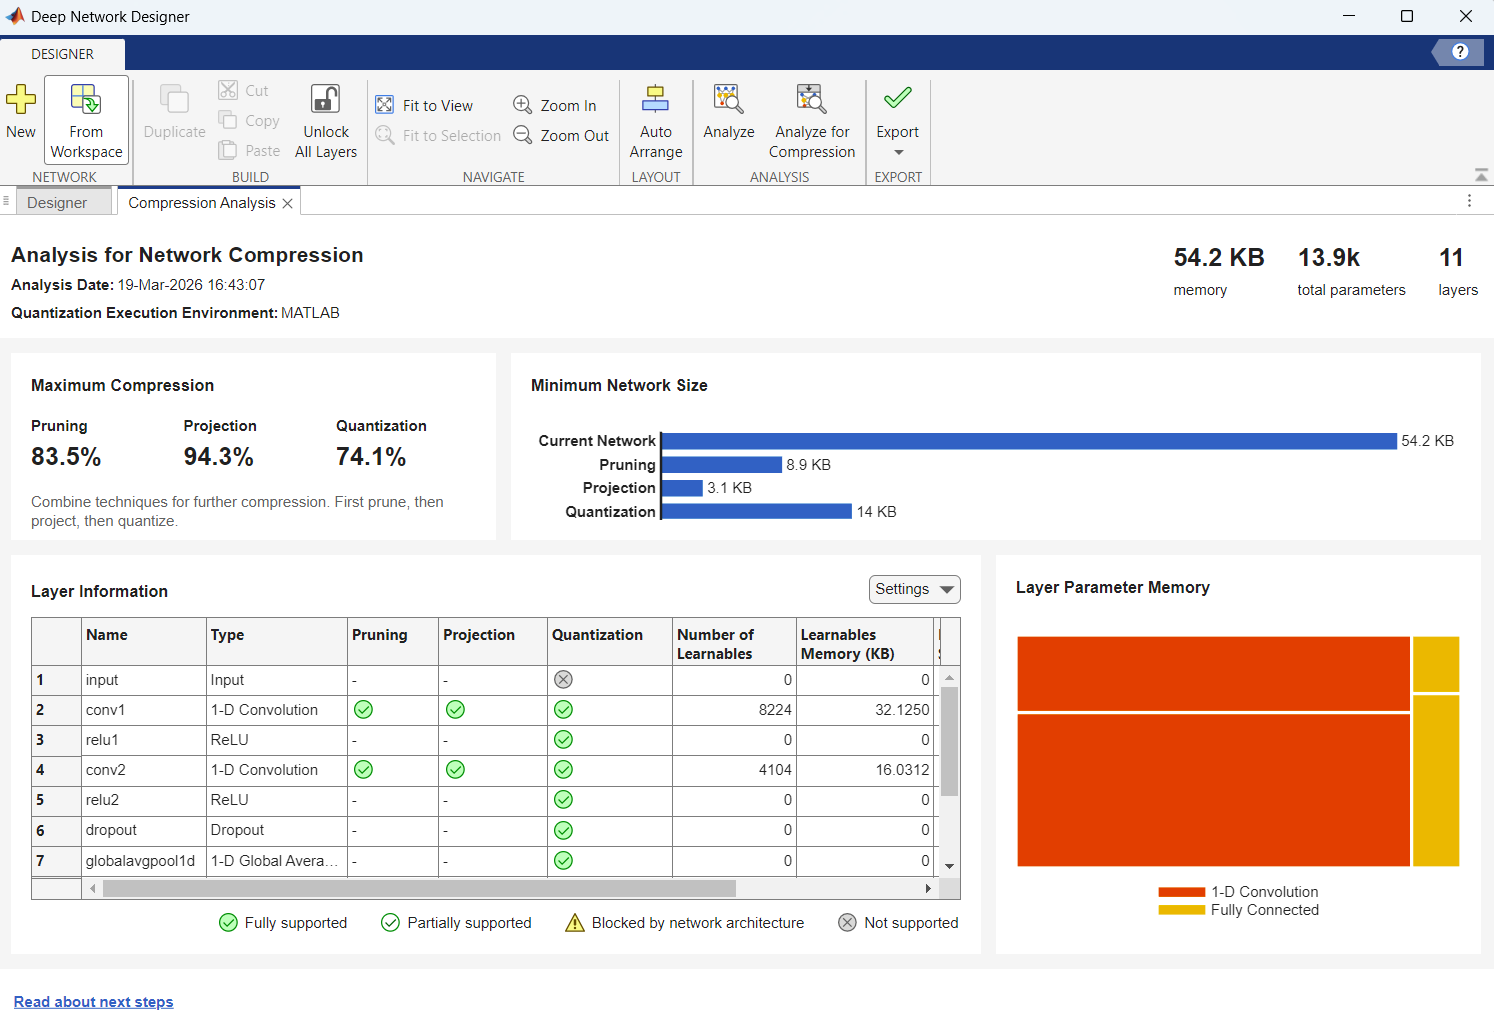

## 2. Compress Network Using Pruning

To prune a convolutional network using Taylor pruning in MATLAB, you will need a [custom training loop](https://www.mathworks.com/help/deeplearning/ug/train-network-using-custom-training-loop.html) to iterate over the following two steps until the network size fulfills your requirements.

- Determine the importance scores of the prunable filters and remove the least important filters by applying a pruning mask.

- Retrain the network for several iterations with the updated pruning mask.

Then, use the final pruning mask to update the network architecture.

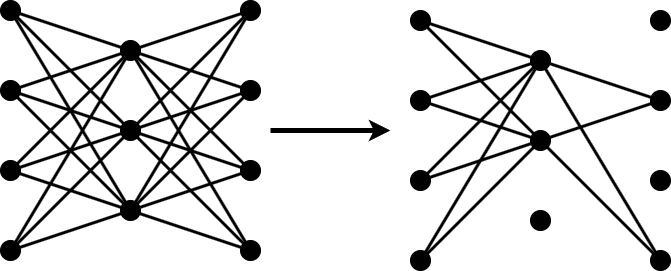

**Set up Pruning**

You can set up the custom training loop by setting up a compression goal of memory reduction.

memoryUncompressed = 54.2; % Learned from Compression Analysis
memoryGoal = 8.9; % Set a goal of model size after pruning and projection 
totalParametersReductionGoal = (memoryUncompressed - memoryGoal)/memoryUncompressed

totalParametersReductionGoal = 0.8358

pruningFraction = 0.7; % Increase this goal if you want to prune more

Calculate the absolute number of learnable parameters in the network using the |countTotalParameters| function defined at the bottom of this example.

totalParametersNetTrained = countTotalParameters(net)

totalParametersNetTrained = 13867

Calculate the desired number of learnables that remain after pruning and projection.

totalParametersGoal = floor(totalParametersNetTrained*(1 - totalParametersReductionGoal))

totalParametersGoal = 2277

Calculate the desired number of learnable parameters that remain after only pruning.

pruningTotalParametersGoal = floor(totalParametersNetTrained*(1 - totalParametersReductionGoal*pruningFraction))

pruningTotalParametersGoal = 5754

Create a Taylor Prunable network from the pretrained network using the [`taylorPrunableNetwork`](docid:nnet_ref#mw_4000fff2-10b1-4f04-8ae4-fc58dfc25946) function.

netPrunable = taylorPrunableNetwork(net);

View the number of convolution filters in the network that are suitable for pruning.

netPrunable.NumPrunables

ans = 33

Set the pruning options. Choosing the pruning options requires empirical analysis and depends on your requirements for network size and accuracy.

- `numPruningIterations` specifies the number of iterations to use for the pruning process.

- maxFiltersToPrunePerIteration specifies the maximum number of filters to prune in each iteration of the pruning loop. In total, a maximum of `numPruningIterations *  maxFiltersToPrunePerIteration` filters are pruned. Note that the filters do not all contain the same number of learnable parameters.

- `numRetrainingEpochs` specifies the number of epochs to use for retraining during each iteration of the pruning loop.

- `initialLearnRate` specifies the initial learning rate used for retraining during each iteration of the pruning loop.

totalParametersNetPruned = totalParametersNetTrained;
maxFiltersToPrunePerIteration = 2;
numRetrainingEpochs = 15; 
initialLearnRate = 0.01;

**Prune Pretrained Network**

Each pruning iteration consists of two steps.

First, retrain the network for `numRetrainingEpochs` epochs to fine-tune it. During the last retraining epoch, compute the importance scores of the prunable filters using the [`updateScore`](docid:nnet_ref#mw_86caa06b-acb6-4994-9ea7-9e95a002d711) function. You can do so inside the custom retraining loop because both steps require iterating over either the entire mini-batch queue or a representative subset. Both steps also require that you compute the activations and gradients of the network.

Second, update the pruning mask using the [`updatePrunables`](docid:nnet_ref#mw_d6b236c8-fb7d-403f-b90f-00ed9eacd6cc) function.

miniBatchSize = 16;
i_epoch=1;
numObservations = size(XTrain,3);
numIterationsPerEpoch = ceil(numObservations/miniBatchSize);
doPrune = true;

while (totalParametersNetPruned > pruningTotalParametersGoal) && doPrune
    % Initialize input arguments for adamupdate.
    tic;
    averageGrad = [];
    averageSqGrad = [];
    fineTuningIteration = 0;    
    YTrainEncode = onehotencode(YTrain,2,'single');

    idx = randperm(numObservations);
    XTrainShuf = XTrain(:,:,idx);
    YTrainShuf = YTrainEncode(idx,:);
    for i = 1:numIterationsPerEpoch
        fineTuningIteration = fineTuningIteration + 1;
        % Mini-batch indices
        startIdx = (i-1)*miniBatchSize + 1;
        endIdx = min(i*miniBatchSize, numObservations);
        batchIdx = startIdx:endIdx;
        % Get batch data
        XBatch = XTrainShuf(:,:,batchIdx);
        YBatch = YTrainShuf(batchIdx,:);
        % Stack XBatch into a 3D array [features x 1 x batch]
        X = cat(3, XBatch);
        X = single(X); % ensure correct type
        % Convert YBatch to one-hot
        Y = YBatch;
        % Convert to dlarray if needed (depends on your model)
        X = dlarray(X, 'TCB'); % or 'CTB' etc., adjust as needed
        [~,state,gradients,pruningActivations,pruningGradients] = dlfeval(@modelLoss,netPrunable,X,Y);
        netPrunable.State = state;
        [netPrunable,averageGrad,averageSqGrad] = adamupdate(netPrunable, gradients, ...
            averageGrad,averageSqGrad, fineTuningIteration, initialLearnRate);
        if i == numRetrainingEpochs
            netPrunable = updateScore(netPrunable,pruningActivations,pruningGradients);
        end
    end
    disp("Epoch "+i_epoch+" complete.");
    % Update the pruning mask.
    netPrunable = updatePrunables(netPrunable,MaxToPrune=maxFiltersToPrunePerIteration);
    % Count learnable parameters.
    updatedTotalParameters = countTotalParameters(netPrunable);
    % Check if no more filters were removed.
    doPrune = updatedTotalParameters < totalParametersNetPruned;
    totalParametersNetPruned = updatedTotalParameters;
    i_epoch=i_epoch+1;
end

Epoch 1 complete.
Epoch 2 complete.
Epoch 3 complete.
Epoch 4 complete.
Epoch 5 complete.
Epoch 6 complete.
Epoch 7 complete.
Epoch 8 complete.
Epoch 9 complete.
Epoch 10 complete.
Epoch 11 complete.


You can compare the layers that has been pruned. Check the number of filters and filter size. Remember to convert the network into a `TaylorPrunableNetwork` object.

prunedNet = dlnetwork(netPrunable)

prunedNet =   dlnetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
    Connections: [10×2 table]
     Learnables: [8×3 table]
          State: [0×3 table]
     InputNames: {'sequenceinput'}
    OutputNames: {'softmax'}
    Initialized: 1

  View summary with summary.


net.Layers([2,4])

ans =   2×1 Convolution1DLayer array with layers:

     1   'conv1'   1-D Convolution   32 256×1 convolutions with stride 1 and padding 'same'
     2   'conv2'   1-D Convolution   8 16×32 convolutions with stride 1 and padding 'same'

prunedNet.Layers([2,4])

ans =   2×1 Convolution1DLayer array with layers:

     1   'conv1'   1-D Convolution   14 256×1 convolutions with stride 1 and padding 'same'
     2   'conv2'   1-D Convolution   4 16×14 convolutions with stride 1 and padding 'same'

**Fine-tune (Retrain) Pruned Network**

It is recommended to fine-tune (retrain) the pruned network to recover the lost accuracy. Note you don't necessarily need all the training data to fine-tune the pruned model. You can also set different options for the fine-tuning.

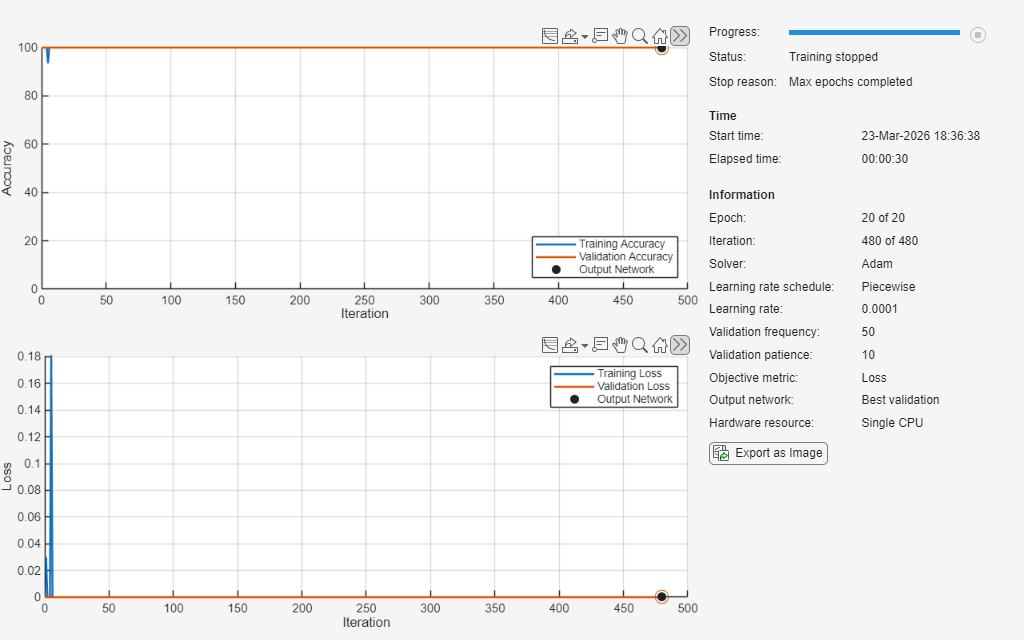

if canUseGPU
    trainOn = "gpu";
else
    trainOn = "cpu";
end
reTrainoptions = trainingOptions("adam", ...
    Metric="accuracy", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=20, ...
    Plots="training-progress", ...
    Verbose=false, ...
    Shuffle="every-epoch", ...
    LearnRateSchedule="piecewise", ...
    ValidationData={XVal,YVal}, ...
    ValidationPatience=10, ...
    OutputNetwork="best-validation-loss", ...
    ExecutionEnvironment=trainOn);
prunedNet = trainnet(XTrain,YTrain,prunedNet,"crossentropy",reTrainoptions);

Calculate the accuracy of the fine-tuned model.

accuracyNetPruned = testnet(prunedNet,XTest,YTest,"accuracy")

accuracyNetPruned = 100

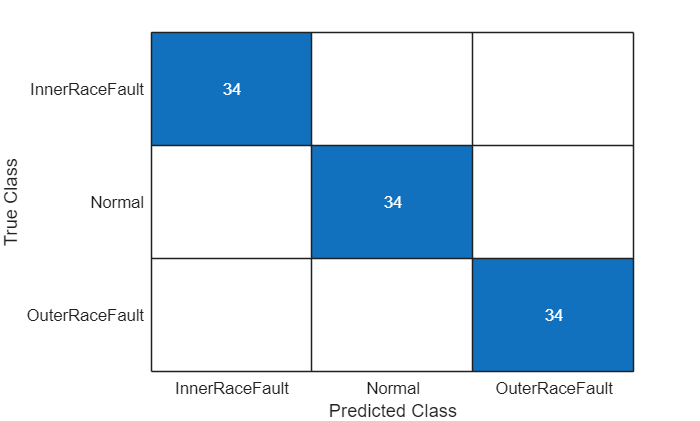

YPredPruned = scores2label(minibatchpredict(prunedNet, XTest),unique(YTrain));
figure
confusionchart(YTest,YPredPruned)

You can check the memory and total parameter of the fine-tuned model from

>>deepNetworkDesigner(prunedNet)

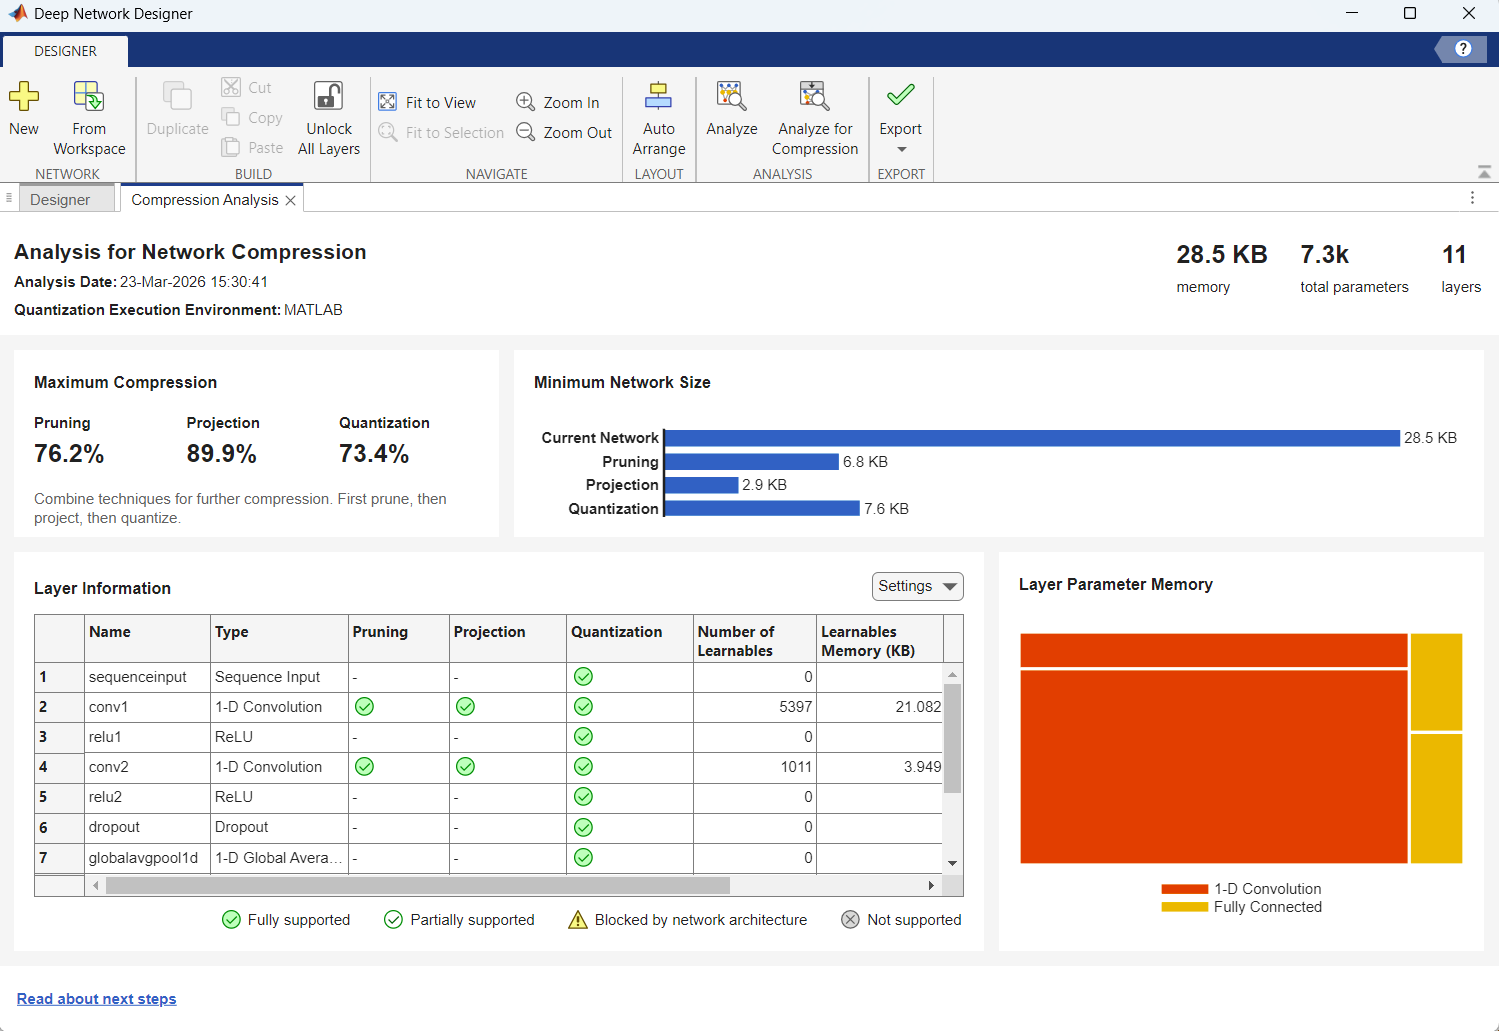

You can optionally save this pruned model for future use.

% save('pruned_net.mat','prunedNet');

## 3. Compress Network Using Projection

Projection allows you to convert large layers with many learnables to one or more smaller layers with fewer total learnable parameters using PCA. 

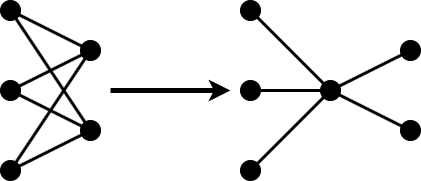

**Project the Pruned Network**

The [`compressNetworkUsingProjection`](https://www.mathworks.com/help/deeplearning/ref/compressnetworkusingprojection.html) function applies principal component analysis (PCA) to the training data to identify the subspace of learnables that result in the highest variance in neuron activations. You can define a neuron PCA object simply with neuronPCA function. 

npca = neuronPCA(prunedNet, dlarray(XTrain,"TCB"), VerbosityLevel='steps')

Using solver mode "direct".
Computing covariance matrices for activations connected to: "conv1/in","conv1/out","conv2/in","conv2/out","fc1/in","fc1/out","fc2/in","fc2/out"
Computing eigenvalues and eigenvectors for activations connected to: "conv1/in","conv1/out","conv2/in","conv2/out","fc1/in","fc1/out","fc2/in","fc2/out"
neuronPCA analyzed 4 layers: "conv1","conv2","fc1","fc2"


npca =   neuronPCA with properties:

                  LayerNames: ["conv1"    "conv2"    "fc1"    "fc2"]
      ExplainedVarianceRange: [0 1]
    LearnablesReductionRange: [0 0.8695]
            InputEigenvalues: {[1.0000]  [14×1 double]  [4×1 double]  [128×1 double]}
           InputEigenvectors: {[1]  [14×14 double]  [4×4 double]  [128×128 double]}
           OutputEigenvalues: {[14×1 double]  [4×1 double]  [128×1 double]  [3×1 double]}
          OutputEigenvectors: {[14×14 double]  [4×4 double]  [128×128 double]  [3×3 double]}


You can define the layers that you want to compress using projection and set goals of variance you would like to retain from the model.

layersToProject = ["conv1"    "conv2"    "fc1"    "fc2"];
explainedVarianceGoal=0.9;

Conduct projection of the CNN model by calling the compressNetworkUsingProjection function.

[projectedNet, info] = compressNetworkUsingProjection(prunedNet, npca,ExplainedVarianceGoal=explainedVarianceGoal,LayerNames=layersToProject);

Compressed network has 30.4% fewer learnable parameters.
Projection compressed 4 layers: "conv1","conv2","fc1","fc2"


Check accuracy of the projected model.

accuracyNetProj = testnet(projectedNet,XTest,YTest,"accuracy")

accuracyNetProj = 68.6274

**Fine-tune the Projected Network**

It is recommended to fine-tune (retrain) the projected network to recover the lost accuracy. Note you don't necessarily need all the training data to fine-tune the projected model. You can also set different options for the fine-tuning.

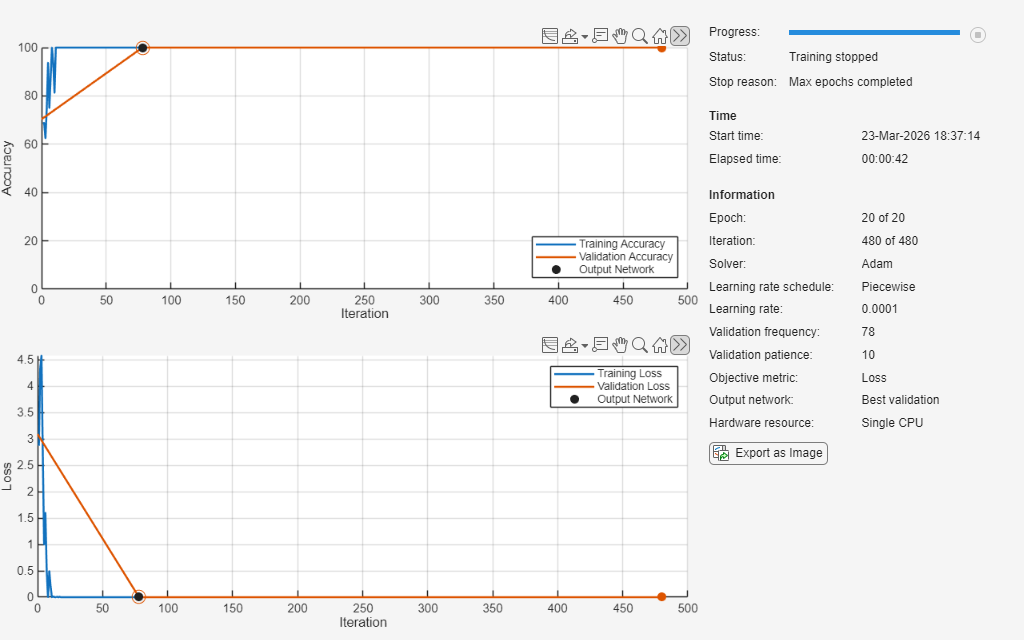

fineTuneOptions = trainingOptions("adam", ...
    Metric="accuracy", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=20, ...
    Plots="training-progress", ...
    Verbose=false, ...
    Shuffle="every-epoch", ...
    LearnRateSchedule="piecewise", ...
    ValidationData={XVal,YVal}, ...
    ValidationFrequency=floor(size(XTrain,1)/64), ...
    ValidationPatience=10, ...
    OutputNetwork="best-validation-loss");
projectedNet = trainnet(XTrain,YTrain,projectedNet,"crossentropy",fineTuneOptions);

Calculate the accuracy of the fine-tuned model.

accuracyNetProjected = testnet(projectedNet,XTest,YTest,"accuracy")

accuracyNetProjected = 100

YPredProjectedFintuned = scores2label(minibatchpredict(projectedNet, XTest),unique(YTrain));
figure
confusionchart(YTest,YPredProjectedFintuned)

You can check the memory and total parameter of the fine-tuned model from

>> deepNetworkDesigner(projectedNet)

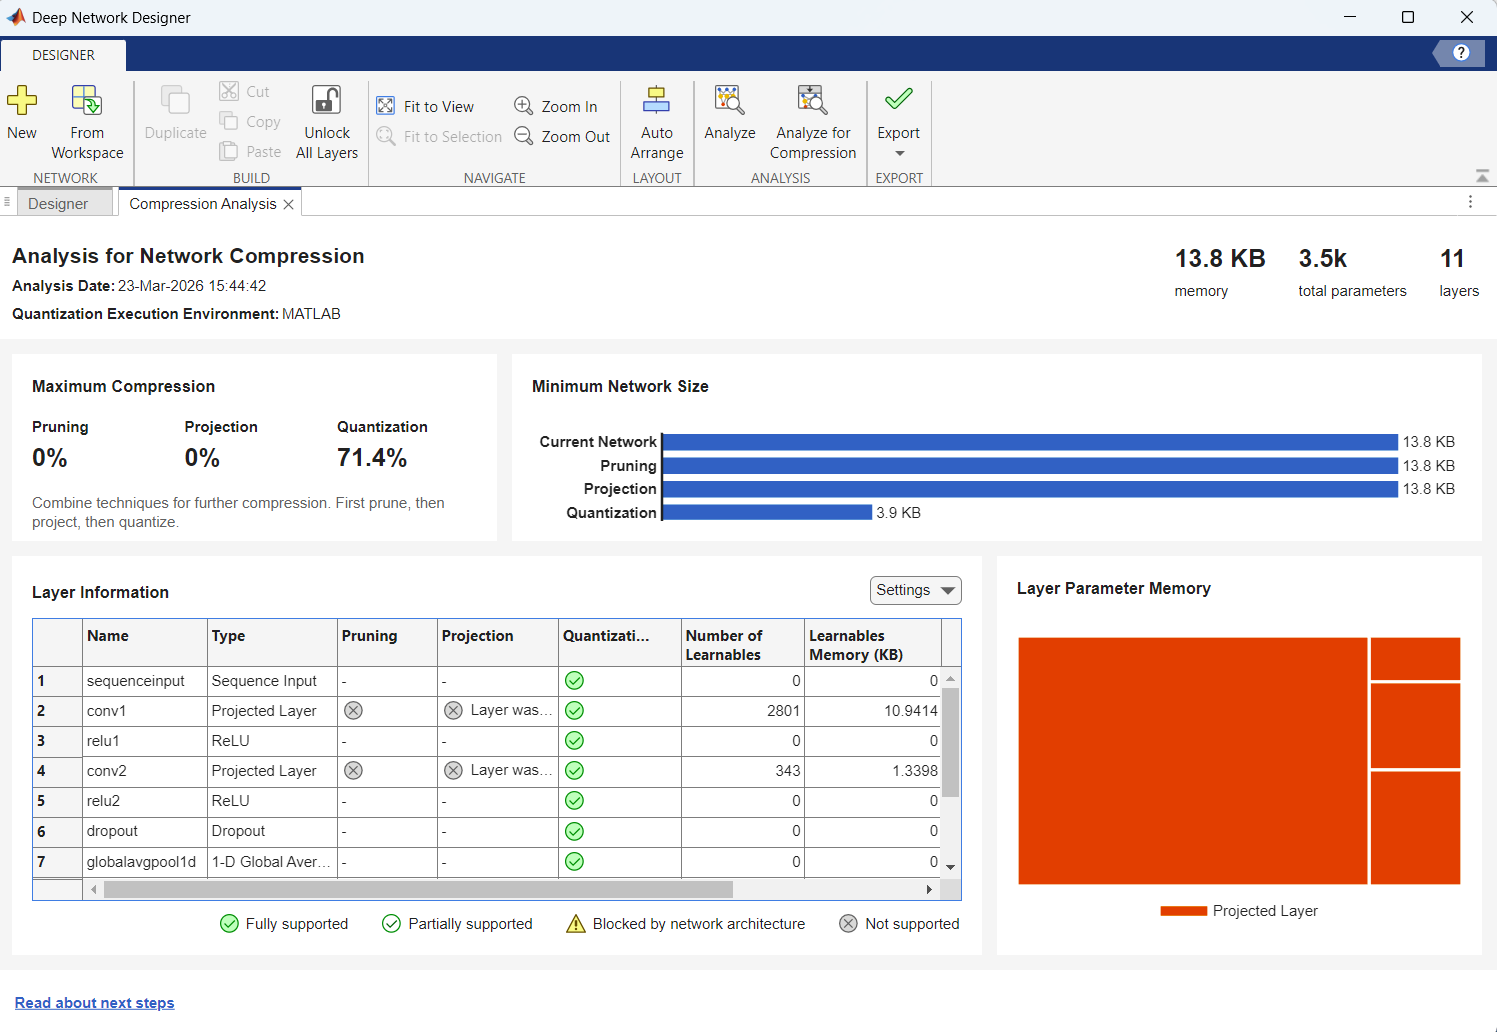

You can optionally save this pruned model for future use.

% save('projected_net.mat','projectedNet');

## 4. Quantize the pruned and projected network 

You can quantize the projected model using the Deep Network Quantizer App. However, in this exercise, you’ll perform the quantization process through the command-line API.

You can start by creating a [`dlquantizer`](https://www.mathworks.com/help/deeplearning/ref/dlquantizer.html) object. Next, use the [`calibrate`](https://www.mathworks.com/help/deeplearning/ref/dlquantizer.calibrate.html) function to determine the dynamic ranges of the layer parameters. Make sure the data you pass to the `calibrate` function is representative of your training data. Next, you can optionally simulate quantization using the [`quantize`](https://www.mathworks.com/help/deeplearning/ref/dlquantizer.quantize.html) function. This function allows you to test the output of your quantized network independent of your hardware target. 

quantObj = dlquantizer(projectedNet,ExecutionEnvironment="MATLAB");
prepareNetwork(quantObj)
dsX = arrayDatastore(XTrain, 'IterationDimension', 3,'OutputType','cell'); % Each read: [5000 x 1]
dsX = gather(dsX);
calResults = calibrate(quantObj,dsX);
quantizedNet = quantize(quantObj,"ExponentScheme","Histogram");

Check accuracy of the projected model.

accuracyNetQuantized = testnet(quantizedNet,XTest,YTest,"accuracy")

accuracyNetQuantized = 100

Use the [`quantizationDetails`](https://www.mathworks.com/help/deeplearning/ref/quantizationdetails.html) function to display details of the quantization, such as a list of quantized layers, the target library, and the quantized learnable parameters.

qDetails = quantizationDetails(quantizedNet)

qDetails = struct with fields:
            IsQuantized: 1
          TargetLibrary: "none"
    QuantizedLayerNames: [14×1 string]
    QuantizedLearnables: [16×3 table]


Save this pruned, projected and quantized model for future use.

save("quantized_net.mat","quantizedNet")

## 5. Compare Model Compression Result    

Let's compare the flash and accuracy of the model after each compression method:

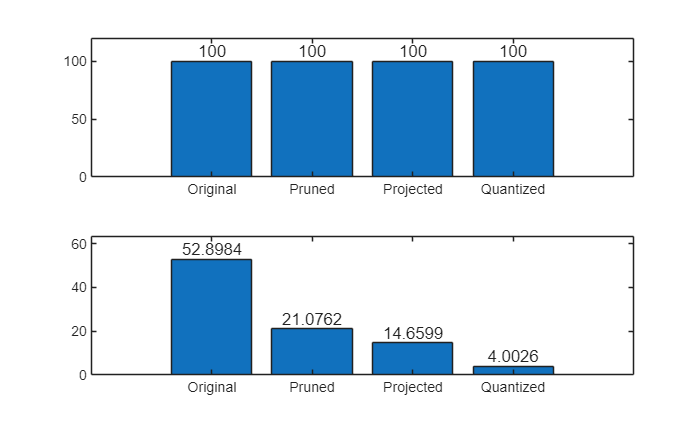

memoryNetTrained = estimateLayerMemory(net);
memoryNetPruned = estimateLayerMemory(prunedNet);
memoryNetProjected = estimateLayerMemory(unpackProjectedLayers(projectedNet));
memoryNetQuantized = estimateLayerMemory(quantizedNet);
memory = [memoryNetTrained memoryNetPruned memoryNetProjected memoryNetQuantized];
accuracy = [accuracyNetOriginal accuracyNetPruned accuracyNetProjected accuracyNetQuantized];
figure
tiledlayout("vertical")
t1 = nexttile;
b1 = bar(t1,accuracy);
x = b1.XData;
for i = 1:length(accuracy)
    text(x(i), accuracy(i), num2str(accuracy(i)), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom');
end
title(t1,"Accuracy")
xticklabels(["Original" "Pruned" "Projected" "Quantized"])
ylim([0,1.2*max(accuracy)])

t2 = nexttile;
b2 = bar(t2,memory);
x = b2.XData;
for i = 1:length(memory)
    text(x(i), memory(i), num2str(memory(i)), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom');
end
title(t2,"Flash Memory (KB)")
xticklabels(["Original" "Pruned" "Projected" "Quantized"])
ylim([0,1.2*max(memory)])

**Helper Function**

function [loss, state, gradients, pruningActivations, pruningGradients] = modelLoss(net,X,Y)

% Calculate network output for training.
[out, state, pruningActivations] = forward(net,X);

% Calculate loss.
loss = crossentropy(out,dlarray(Y'),'TargetCategories','independent');

% Compute pruning gradients.
gradients = dlgradient(loss,net.Learnables);
pruningGradients = dlgradient(loss,pruningActivations);
end

Calculate Memory of Supported Layers

function layerMemoryInKB = estimateLayerMemory(net)
    info = estimateNetworkMetrics(net);
    layerMemoryInMB = sum(info.("ParameterMemory (MB)"));
    layerMemoryInKB = layerMemoryInMB * 1000;
end

function numParameters = countTotalParameters(net)
    arguments
        net dlnetwork
    end
    numLearnables = cellfun(@numel,net.Learnables.Value);
    numStates = cellfun(@numel,net.State.Value);
    numParameters = sum(numLearnables) + sum(numStates);
end

function numLearnables = countLearnables(net)
    numLearnables = sum(cellfun(@numel,net.Learnables.Value));
end